% Rotational vs Continuous Grazing (fixed N = 3)

% Parameters 
A = 100;                % total area (ha)
K_tot = 3000000;        % total carrying capacity (kg)
r = 0.04;               % growth rate (1/day)
C = 400;                % cattle number
a = 1e-4;               % grazing efficiency
thr_frac = 0.2;         % threshold fraction to move cattle
Tmax = 365;             % simulation days
dt = 0.1;               % time step (day)

fprintf('Area: 100 hectares\n');

Area: 100 hectares


fprintf('Carrying capacity: 3 000 000 kg\n');

Carrying capacity: 3 000 000 kg


fprintf('Carrying capacity per hectare: 3 000 kg/ha\n');

Carrying capacity per hectare: 3 000 kg/ha


fprintf('Growth rate: 0.04 per day\n'); 

Growth rate: 0.04 per day


fprintf('Cattle: 400\n');

Cattle: 400


fprintf('Grazing efficiency: 0.0001\n');

Grazing efficiency: 0.0001


fprintf('Threshold fraction: 0.2\n');

Threshold fraction: 0.2




% fixed number of subpastures = 3
N = 3;
K_i = K_tot / N;
A_i = A / N;
G = K_i * ones(1, N); % all start at carrying capacity
t = 0;
current = 1;  % start grazing paddock 1

time_hist = [];
G_hist = zeros(round(Tmax/dt), N);
current_hist = zeros(round(Tmax/dt), 1);
idx = 1;

while t < Tmax
    I = zeros(1, N);
    I(current) = 1;
    
    for i = 1:N
        if I(i) == 1
            dG = r * G(i) * (1 - G(i)/K_i) - G(i) * C * a;
        else
            dG = r * G(i) * (1 - G(i)/K_i);
        end
        G(i) = max(0, G(i) + dG * dt);
    end
    
    t = t + dt;
    time_hist(idx) = t;
    G_hist(idx, :) = G;
    current_hist(idx) = current;
    idx = idx + 1;
    
    if G(current) < thr_frac * K_i
        current = mod(current, N) + 1;  % move to next paddock
    end
end

time_hist = time_hist(1:idx-1);
G_hist = G_hist(1:idx-1, :);
current_hist = current_hist(1:idx-1);

fprintf('Using fixed N = %d subpastures.\n', N);

Using fixed N = 3 subpastures.


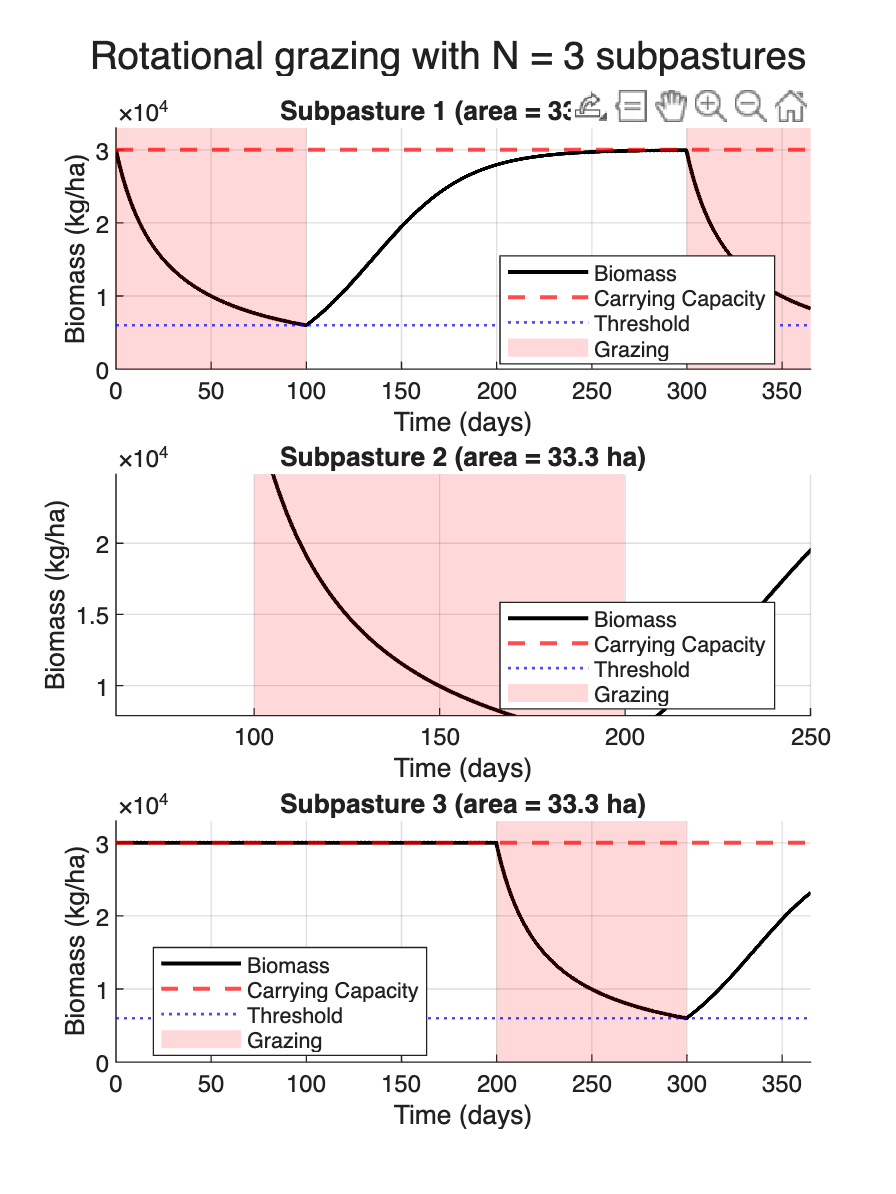



% Plot individual subpastures
figure('Position', [50, 50, 900, 1200]);

for i = 1:N
    subplot(N, 1, i);
    hold on;
    
    % Biomass
    plot(time_hist, G_hist(:, i) / A_i, 'k-', 'LineWidth', 1.5);
    yline(K_i / A_i, 'r--', 'LineWidth', 1.5);
    yline(thr_frac * K_i / A_i, 'b:', 'LineWidth', 1);
    
    % Shading 
    graze_idx = find(current_hist == i);
    if ~isempty(graze_idx)
        seg_starts = graze_idx([1, find(diff(graze_idx) > 1) + 1]);
        seg_ends   = graze_idx([find(diff(graze_idx) > 1), end]);
        for s = 1:length(seg_starts)
            patch([time_hist(seg_starts(s)), time_hist(seg_ends(s)), ...
                   time_hist(seg_ends(s)), time_hist(seg_starts(s))], ...
                  [0, 0, K_i/A_i*1.1, K_i/A_i*1.1], ...
                  'r', 'FaceAlpha', 0.15, 'EdgeColor', 'none');
        end
    end
    
    xlabel('Time (days)'); ylabel('Biomass (kg/ha)');
    title(sprintf('Subpasture %d (area = %.1f ha)', i, A_i));
    legend({'Biomass', 'Carrying Capacity', 'Threshold', 'Grazing'}, 'Location', 'best');
    grid on;
    xlim([0 Tmax]); ylim([0, K_i/A_i * 1.1]);
end
sgtitle(sprintf('Rotational grazing with N = %d subpastures', N));

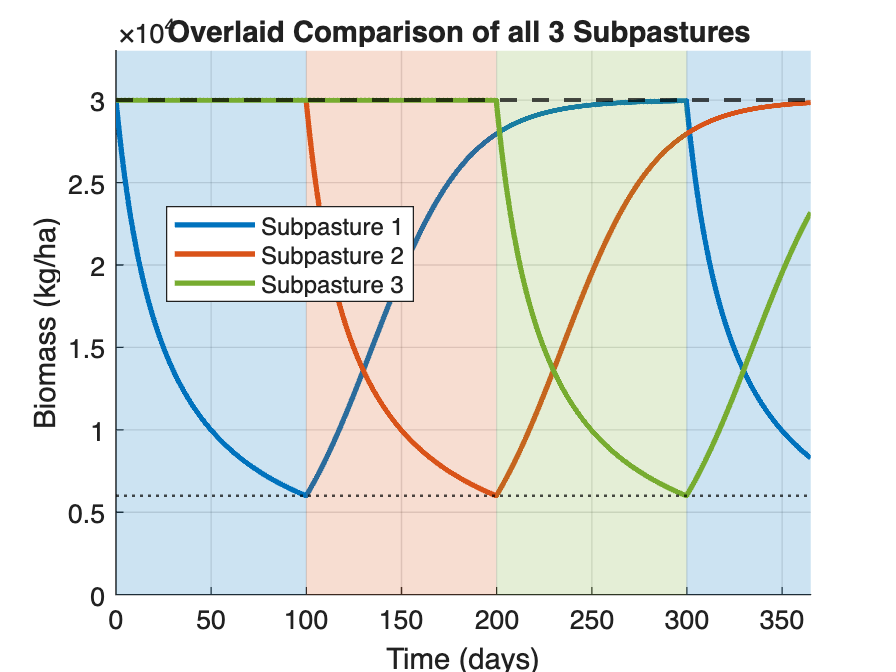



% Plot comparison of all subpastures  
figure('Position', [100, 100, 800, 600]);
hold on;

colours = {[0 0.447 0.741], [0.850 0.325 0.098], [0.466 0.674 0.188], ...
           [0.929 0.694 0.125], [0.494 0.184 0.556], [0.301 0.745 0.933]};
line_handles = gobjects(1, N);

for i = 1:N
    % Shade grazing 
    graze_idx = find(current_hist == i);
    if ~isempty(graze_idx)
        seg_starts = graze_idx([1, find(diff(graze_idx) > 1) + 1]);
        seg_ends   = graze_idx([find(diff(graze_idx) > 1), end]);
        for s = 1:length(seg_starts)
            patch([time_hist(seg_starts(s)), time_hist(seg_ends(s)), ...
                   time_hist(seg_ends(s)), time_hist(seg_starts(s))], ...
                  [0, 0, K_i/A_i*1.1, K_i/A_i*1.1], ...
                  colours{i}, 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        end
    end
    
    % Plot biomass trajectory
    line_handles(i) = plot(time_hist, G_hist(:, i) / A_i, ...
                           'Color', colours{i}, 'LineWidth', 2, ...
                           'DisplayName', sprintf('Subpasture %d', i));
end

yline(K_i / A_i, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Carrying Capacity (K)');
yline(thr_frac * K_i / A_i, 'k:', 'LineWidth', 1, 'DisplayName', 'Threshold');

xlabel('Time (days)'); ylabel('Biomass (kg/ha)');
title(sprintf('Overlaid Comparison of all %d Subpastures ', N));
legend([line_handles, findobj(gca, 'Type', 'Line', 'LineStyle', '--'), ...
        findobj(gca, 'Type', 'Line', 'LineStyle', ':')], ...
       'Location', 'best');
grid on;
xlim([0 Tmax]); ylim([0, K_i/A_i * 1.1]);



% Averages (rotational)
G_total_rot = sum(G_hist, 2);
avg_rot_ha = mean(G_total_rot) / A;


% Numerical results
fprintf('\nAverage biomass over 365 days (kg/ha):\n');


Average biomass over 365 days (kg/ha):


fprintf('  Continuous grazing:  %.1f\n', avg_cont_ha);

  Continuous grazing:  5635.0


fprintf('  Rotational grazing:  %.1f\n', avg_rot_ha);

  Rotational grazing:  21050.8
